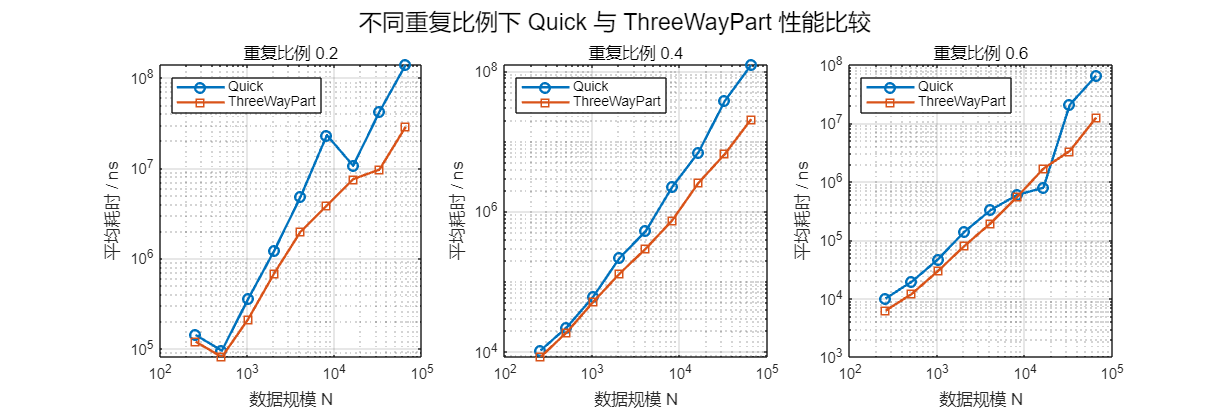

% 数据规模
N = [256 512 1024 2048 4096 8192 16384 32768 65536];

% Quick耗时数据 (纳秒) 对应重复比例 0.2, 0.4, 0.6
Quick_02 = [141548.60 94851.40 354872.40 1224182.60 4840590.60 23220206.80 10623775.80 42027994.80 139623459.00];
Quick_04 = [10456.40 22475.00 61050.00 217891.60 528662.80 2243534.20 7005167.60 37862183.00 123043697.00];
Quick_06 = [10009.80 19439.60 47189.40 139450.40 327775.60 593397.60 789401.60 20711311.20 65165810.80];

% ThreeWayPart耗时数据 (纳秒) 对应重复比例 0.2, 0.4, 0.6
ThreeWay_02 = [119245.80 80703.60 211624.40 687822.40 1981532.40 3868664.40 7556459.00 9634332.20 28683332.20];
ThreeWay_04 = [8447.80 19115.00 51445.40 130230.40 296626.80 749613.20 2568456.00 6605552.40 20718795.60];
ThreeWay_06 = [6177.40 12017.20 29740.80 79720.40 195336.20 549655.00 1674154.80 3351429.00 12469345.60];

% 绘图

% 调整 figure 宽度和高度（单位像素）
figure('Position',[100 100 1500 500]);  % 左下角X,Y，宽1500，高500

% 子图 1 - 重复比例 0.2
subplot(1,3,1);
loglog(N, Quick_02, '-o','LineWidth',1.5,'DisplayName','Quick'); hold on;
loglog(N, ThreeWay_02, '-s','LineWidth',1.5,'DisplayName','ThreeWayPart');
xlabel('数据规模 N'); ylabel('平均耗时 / ns'); title('重复比例 0.2');
legend('Location','northwest'); grid on;

% 子图 2 - 重复比例 0.4
subplot(1,3,2);
loglog(N, Quick_04, '-o','LineWidth',1.5,'DisplayName','Quick'); hold on;
loglog(N, ThreeWay_04, '-s','LineWidth',1.5,'DisplayName','ThreeWayPart');
xlabel('数据规模 N'); ylabel('平均耗时 / ns'); title('重复比例 0.4');
legend('Location','northwest'); grid on;

% 子图 3 - 重复比例 0.6
subplot(1,3,3);
loglog(N, Quick_06, '-o','LineWidth',1.5,'DisplayName','Quick'); hold on;
loglog(N, ThreeWay_06, '-s','LineWidth',1.5,'DisplayName','ThreeWayPart');
xlabel('数据规模 N'); ylabel('平均耗时 / ns'); title('重复比例 0.6');
legend('Location','northwest'); grid on;

sgtitle('不同重复比例下 Quick 与 ThreeWayPart 性能比较');